1.Find an interpolating polynomial using matrices to determine y at x = 3. Try linear, quadratic, and cubic polynomials between appropriate data points first, then try a polynomial that interpolates the entire data set. Make one plot with the data along with the 4 interpolating polynomials, then another plot with degree of interpolating polynomial on the horizontal axis and the estimated value of y at x = 3 on the vertical axis.

disp('------------------------------------ Q1 --------------------------------------------')

------------------------------------ Q1 --------------------------------------------


   14.0363

   11.3750

   11.3750

   11.3750



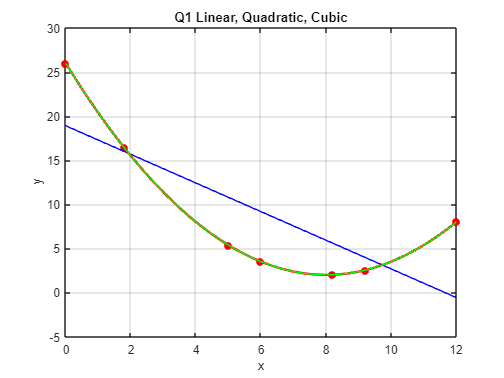

q1()

4. Use any built-in Matlab functions to do inverse interpolation to estimate the value of x at which f(x) = 1.7.

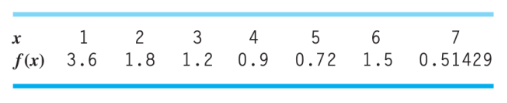

disp('------------------------------------ Q4 --------------------------------------------')

------------------------------------ Q4 --------------------------------------------


    6.5928
    6.2216
    2.0909



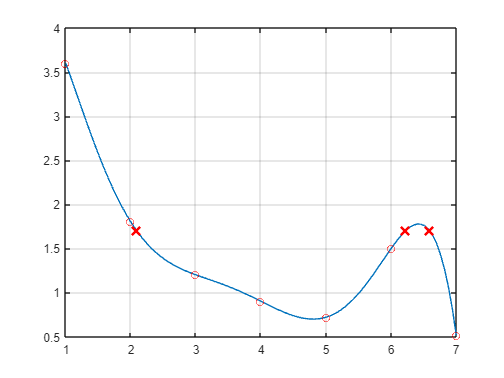

q4()

5. Use the portion of the given steam table for superheated water at 200 MPa to find: 

    (a) the corresponding ­entropy *s* for a specific volume *υ* of 0.118 with linear interpolation, 

    (b) the same corresponding entropy using quadratic interpolation, and 

    (c) the volume corresponding to an entropy of 6.45 using inverse interpolation of both the linear and quadratic cases.

disp('------------------------------------ Q5 --------------------------------------------')

------------------------------------ Q5 --------------------------------------------


    6.6472

    6.6515

Linear : Value of V at  entropy of 6.45 : 
    0.1058

Quadratic : Value of V at  entropy of 6.45 : 
    0.1058



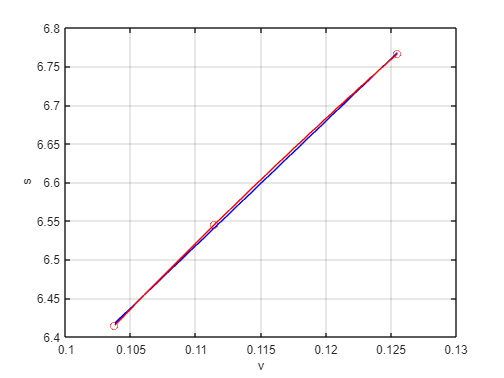

q5()

6. Sample the function, f = 1 / (1 + 25x^2), 10 times equally spaced from -1 to 1 and store the results as data y, with x being the sample points. Use Matlab’s spline function to fit a curve to this data (note that Newton and Lagrange polynomials do not work for this).

disp('------------------------------------ Q6 --------------------------------------------')

------------------------------------ Q6 --------------------------------------------


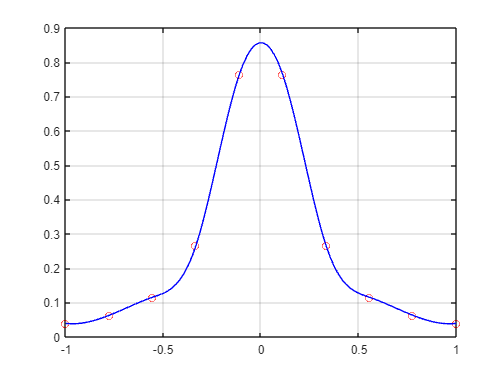

q6()

7. Interpolate the following data using cubic splines with knot-a-not end condition and also with clamped end condition with first derivatives set equal to 0. Plot both curves along with the data on the same graph. Use both interpolating methods to estimate the y-value when x = 1.5.

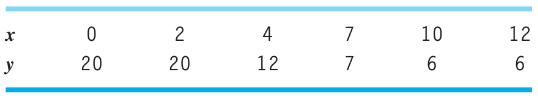

disp('------------------------------------ Q7 --------------------------------------------')

------------------------------------ Q7 --------------------------------------------


   21.3344

   20.5701



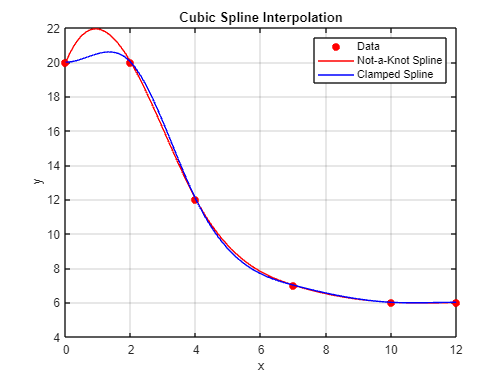

q7()

8. The following grid represents 6 pixels of an image and their corresponding colour value (one of RGB for example).

        

	We zoom in and create more pixels which we need to interpolate in order to smooth out the image.

        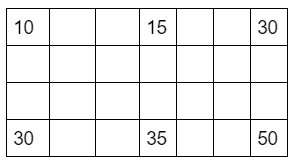

	Use linear interpolation to find the missing values (store the values as a matrix 

	containing the colour value at each of the coordinate locations).

disp('------------------------------------ Q8 --------------------------------------------')

------------------------------------ Q8 --------------------------------------------


q8()

   10.0000   11.6667   13.3333   15.0000   20.0000   25.0000   30.0000
   16.6667   18.3333   20.0000   21.6667   26.6667   31.6667   36.6667
   23.3333   25.0000   26.6667   28.3333   33.3333   38.3333   43.3333
   30.0000   31.6667   33.3333   35.0000   40.0000   45.0000   50.0000



 -------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

function q1()
    x = [0, 1.8, 5, 6, 8.2, 9.2, 12];
    y = [26, 16.415, 5.375, 3.5, 2.015, 2.54, 8];

    plot(x, y, 'ro', MarkerFaceColor='r')
    xlabel('x')
    ylabel('y')
    title('Q1 Linear, Quadratic, Cubic')
    grid on

    % Linear Interpolate | Slides 1 | Matrix Form: p1x + p2
    linear_A = [x', ones(size(x'))];
    % dont use .\
    linear_p = linear_A \ y';
    target_y = linear_p(1)*3 + linear_p(2);     %3 is x target
    disp(double(target_y))

    xx = (linspace(0, 12));
    linear_y = polyval(linear_p, xx);
    hold on
    plot(xx, linear_y, 'b')

    % Quadratic Interpolate 
    qua_A = [x'.^2, x', ones(size(x'))];
    qua_p = qua_A \ y';
    target_y = qua_p(1)*3^2 + qua_p(2)*3 + qua_p(3);
    disp(double(target_y))

    qua_y = polyval(qua_p, xx);
    plot(xx, qua_y, 'r', LineWidth=2)

    % Cubic Interpolate
    cub_A = [x'.^3, x'.^2, x', ones(size(x'))];
    cub_p = cub_A \ y';
    target_y = cub_p(1)*3^3 + cub_p(2)*3^2 + cub_p(3)*3 + cub_p(4);
    disp(double(target_y))

    cub_y = polyval(cub_p, xx);
    plot(xx, cub_y, 'g')

    Q1sol = interpolatePolynomial(x', y', 2, 3);
    disp(Q1sol)

    hold off
end


function q4()
    % Practical Problems 9 Question 4
    
    % Step 1: Data | Slides 22 - 26
    x = [1 2 3 4 5 6 7];
    y = [3.6 1.8 1.2 0.9 0.72 1.5 0.51429];
    
    n = length(x);
    
    p = polyfit(x, y, n-1);
    
    xx = linspace(1, 7);
    yy = polyval(p, xx);

    % Step 2: Plot
    plot(xx, yy);
    hold on
    grid on
    
    % Step 3: Root finding | Inverse Interpolation
    y_target = 1.7;
    
    % p(1)x^n + p(2)x^n-1 + p(3)x^n-2 + .... +p(n) - y_target = 0 / root
    root = roots([p(1) p(2) p(3) p(4) p(5) p(6) p(7) - y_target]);
    root = root(imag(root) == 0);
    root = root(root >= 0 & root <= 7);
    disp(root)
    
    func = @(x) p(1).*x.^6 + p(2).*x.^5 + p(3).*x.^4 + p(4).*x.^3 + p(5).*x.^2 + p(6).*x + p(7);

    plot(root, func(root), 'rx', MarkerSize=10, LineWidth=2);
    scatter(x, y, 'ro');
    xlim([1, 7]);
    hold off
end

function q5()
    v = [0.10377, 0.11144, 0.12547];
    s = [6.4147, 6.5453, 6.7664];

    plot(v, s, 'ro');
    xlabel('v')
    ylabel('s')
    grid on
    hold on
    
    % a. linear
    aLinear = interpolatePolynomial(v', s', 1, 0.118);  %value of s at v = 0.118
    disp(aLinear)

    rangeX = linspace(min(v), max(v), 10);  % create more value of x, make line smooth 
    aP = polyfit(v, s, 1);                  % find P or coefficient
    rangeY = polyval(aP, rangeX);           % get the new Y value to plot
    plot(rangeX, rangeY, 'b')

    % b. Quadratic
    aQuad = interpolatePolynomial(v', s', 2, 0.118);
    disp(aQuad)
    
    bP = polyfit(v, s, 2);
    rangeY = polyval(bP, rangeX);
    plot(rangeX, rangeY, 'r')

    % c. Inverse Interpolation
    linP = polyfit(v, s, 1);
    linRoots = roots([linP(1) linP(2) - 6.45]);
    disp("Linear : Value of V at  entropy of 6.45 : ")
    disp(linRoots)

    quadP = polyfit(v, s, 2);
    quadRoots = roots([quadP(1) quadP(2) quadP(3) - 6.45]);             % - 6.45 = - targetYvalue
    quadRoots = quadRoots(quadRoots >= min(v) & quadRoots <= max(v));   % limits the value of v to be in it's range
    disp("Quadratic : Value of V at  entropy of 6.45 : ")
    disp(quadRoots)
    hold off
end

function q6()
    % Step 1: Generate equally spaced sample points
    x = linspace(-1, 1, 10);

    % Step 2: Compute corresponding y values using the function f(x)
    y = 1 ./ (1 + 25*x.^2);
    plot(x, y, 'ro')
    hold on
    grid on
    
    % Step 3: Fit a curve using Matlab's spline function
    xfit = linspace(-1, 1, 100); % Generate points for the fitted curve
    yfit = spline(x, y, xfit);

    plot(xfit, yfit, 'b')
    hold off
end

function q7()
    x = [0, 2, 4, 7, 10, 12];
    y = [20, 20, 12, 7, 6, 6];

    % Step 2: Interpolate
    % If we know the first derivertive and input = clampped
    % If we make 3rd derivertive at 2nd and 2nd to last point = not-a-knot
    % 2nd derivative set to 0 = natural spline
    xx = linspace(0, 12, 100);  % Use the range of the original data
    
    yy_not = spline(x, y, 1.5);
    yy_clamped = spline(x, [0, y, 0], 1.5);     % clamped spline to have zero first derivatives at both the beginning and ending points
    disp(yy_not)
    disp(yy_clamped)
    
    yy_not_graph = spline(x, y, xx);            % create curve
    yy_clamped_graph = spline(x, [0 y 0], xx);
    
    plot(x, y, 'ro', 'MarkerFaceColor', 'r');
    hold on;
    grid on;
    plot(xx, yy_not_graph, 'r', 'DisplayName', 'not-a-Knot Spline');
    plot(xx, yy_clamped_graph, 'b', 'DisplayName', 'Clamped Spline');
    xlabel('x');
    ylabel('y');
    title('Cubic Spline Interpolation');
    legend('Data', 'Not-a-Knot Spline', 'Clamped Spline');
end

function q8()
    x = 1:3;
    y = 1:2;
    z = [10, 15, 30; 30, 35, 50];

    % Step 2: Interpolate
    xx = linspace(min(x), max(x), 7);       % make 7 x blocks
    yy = linspace(min(y), max(y), 4);       % make 4 y blocks
    [X, Y] = meshgrid(xx, yy);              % value of xx * yy in matrix, regular grid of coordinates

    % example of 1 variable interp : interp1(x,y,xx,'method')
    zint = interp2(x, y, z, X, Y);          % use X and Y for grid location, in other context can X and Y can be target
    disp(zint)
end

Functions

function x_interp = interpolatePolynomial(x, y, degree, x_interp)
    if length(x) ~= length(y)  degree >= length(x);
        error('Input data is invalid for interpolation');
    end

    % Create the Vandermonde matrix for the given degree
    A = zeros(length(x), degree + 1);
    for i = 1:(degree + 1)
        A(:, i) = x.^(degree + 1 - i);
    end

    % Solve for the coefficients using left division
    coefficients = A \ y;

    % Evaluate the polynomial at the interpolation points
    B = zeros(length(x_interp), degree + 1);
    for i = 1:(degree + 1)
        B(:, i) = x_interp.^(degree + 1 - i);
    end
    y_interp = B * coefficients;

    % x_interp now contains the interpolated values of x
    x_interp = y_interp;
end

function coefficients = betterpolyfit(x, y, degree)
    if length(x) ~= length(y)  degree >= length(x);
        error('Input data is invalid for interpolation');
    end

    % Create the Vandermonde matrix for the given degree
    A = zeros(length(x), degree + 1);
    for i = 1:(degree + 1)
        A(:, i) = x.^(degree + 1 - i);
    end

    % Solve for the coefficients using left division
    coefficients = A \ y;
end